# Raúl Correa Ocañas

Tarea 2

A01722401

26 de mayo de 2023

clear all
clc

## Velocidad x Tiempo

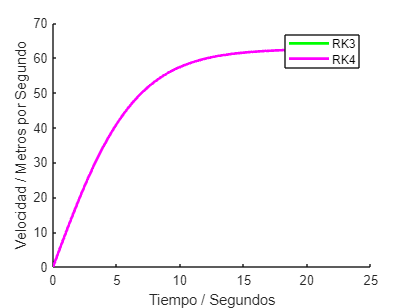

g = 9.81; % ms^-2
c_d = 0.225; % kg/m.
m = 90; % kg

t_1 = 0; % t inicial
t_f = 21; % t final
h = 0.1; % Paso delta h

dvdt = @(t,v) g-c_d*(v.^2)/m; % eq dif
v(1) = 0; % v inicial

[t, v_RK3] = RK3(dvdt,t_1,t_f,v,h);
[t, v_RK4] = RK4(dvdt,t_1,t_f,v,h);

figure(1)
hold on

a1 = plot(t, v_RK3, 'g', 'LineWidth', 2); % RK3 - verde
a2 = plot(t, v_RK4, 'm', 'LineWidth', 2); % RK4 - morado

hold off

xlabel('Tiempo / Segundos')
ylabel('Velocidad / Metros por Segundo')
legend([a1,a2], 'RK3', 'RK4')

## Desplazamiento

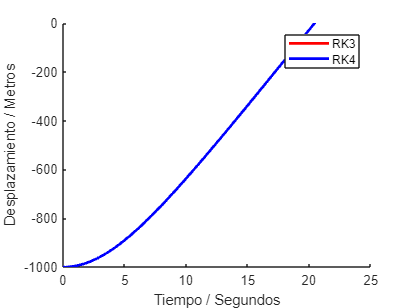

d_RK3(1) = -1000;
d_RK4(1) = -1000;

for i = 1:length(t)-1
    d_RK3(i+1) = d_RK3(i) + v_RK3(i)*h;
end
    
for i = 1:length(t)-1
    d_RK4(i+1) = d_RK4(i) + v_RK4(i)*h;
end

figure(2)
hold on

a3 = plot(t,d_RK3, 'r', 'LineWidth', 2);
a4 = plot(t,d_RK4, 'b', 'LineWidth', 2);

hold off

xlabel('Tiempo / Segundos')
ylabel('Desplazamiento / Metros')
y_min = min([d_RK3, d_RK4]);
y_max = 0;
ylim([y_min y_max])
legend([a3,a4], 'RK3', 'RK4')

## Resultados

T = table(t', d_RK3', d_RK4', v_RK3', v_RK4', 'VariableNames', {'t', 'd_RK3', 'd_RK4','v_RK3', 'v_RK4'});
disp(T)

     t       d_RK3      d_RK4      v_RK3      v_RK4 
    ____    _______    _______    _______    _______

       0      -1000      -1000          0          0
     0.1      -1000      -1000    0.98092    0.98092
     0.2     -999.9     -999.9     1.9614     1.9614
     0.3    -999.71    -999.71     2.9408     2.9408
     0.4    -999.41    -999.41     3.9189     3.9189
     0.5    -999.02    -999.02      4.895      4.895
     0.6    -998.53    -998.53     5.8687     5.8687
     0.7    -997.94    -997.94     6.8396     6.8396
     0.8    -997.26    -997.26     7.8072     7.8072
     0.9    -996.48    -996.48      8.771      8.771
       1     -995.6     -995.6     9.7306     9.7306
     1.1    -994.63    -994.63     10.686     10.686
     1.2    -993.56    -993.56     11.635     11.635
     1.3     -992.4     -992.4    

Por lo tanto se estima que al rededor del segundo 20.42 (s), el paracaidista llega al piso.

## Método de Runge Kutta Orden 3

function [x,y] = RK3(f,x_1,x_f,y,h)
    x = x_1:h:x_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        k3 = f(x(i) + h, y(i) - k1*h + 2*k2*h);
        y(i+1) = y(i) + (k1 + 4*k2 + k3)*h/6;
    end
end

## Método de Runge Kutta Orden 4

function [x,y] = RK4(f,x_1,x_f,y,h)
    x = x_1:h:x_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        k3 = f(x(i) + h/2, y(i) + k2*h/2);
        k4 = f(x(i) + h, y(i) + k3*h);
        y(i+1) = y(i) + (k1 + 2*k2 + 2*k3 + k4)*h/6;
    end
end